# OOK Signal Simulation

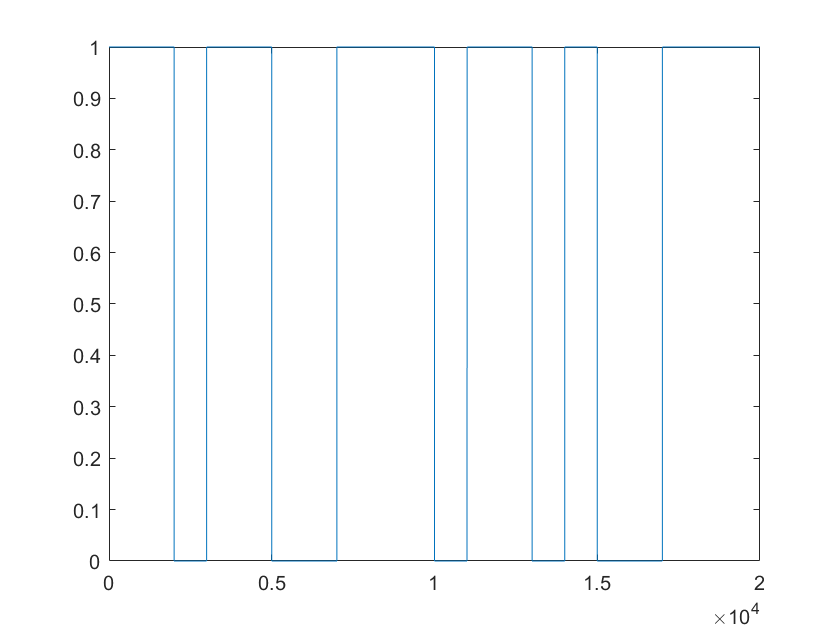

fs = 10000;
t_ari = 1e-1;

len = 20;                   %number of generated bit
f = randi([0 1], len, 1);
encoded = ones(1, len*t_ari*fs);
for i = 1:length(f)
    encoded((i-1)*fs*t_ari+1:i*fs*t_ari) = repelem(f(i),fs*t_ari);
end
plot(encoded)

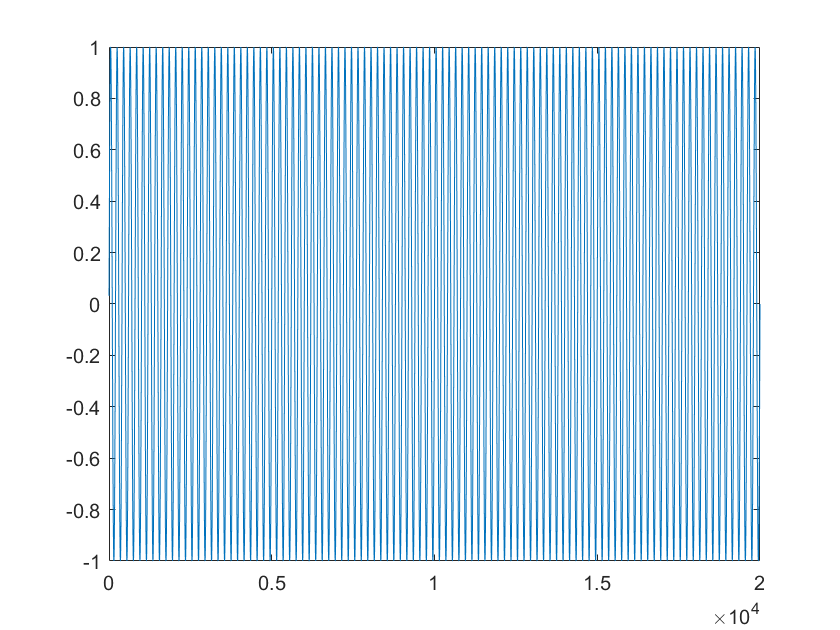


t = 1/fs:1/fs:len*t_ari;
f = 50;
carrier = sin(2*pi*f*t);
plot(carrier)

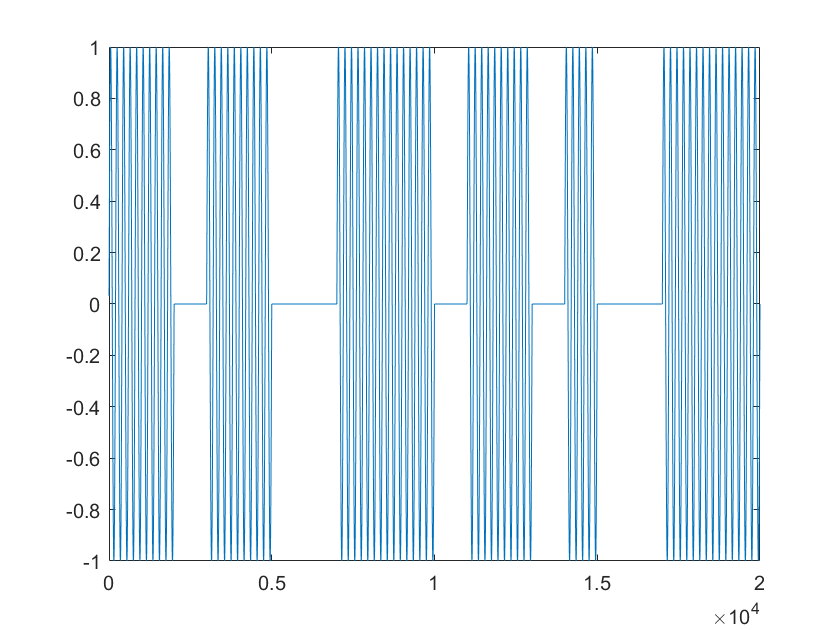


modulated = encoded.*carrier;
plot(modulated)

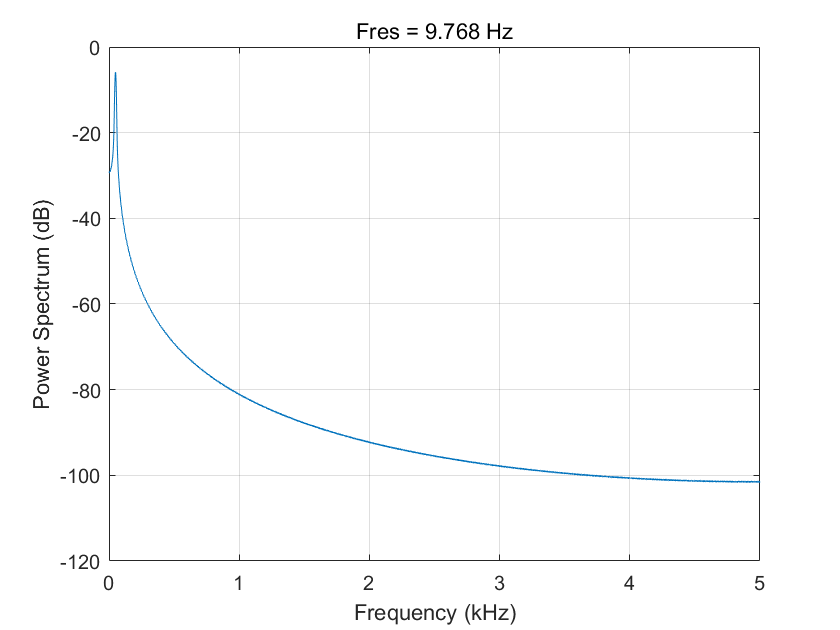

pspectrum(modulated, fs)

spectrogram(modulated, fs)